clear all; clc;
load('needle/needlecrosssectional.mat');

c0      = 1540;
f0      = Trans.frequency*1e6;            % center frequency in MHz
x_trnsd = (-63:64)*0.3e-3;                % distance between the elements

fSample = Receive(1).decimSampleRate*1e6; % sampling frequency
dt      = 1.0/fSample;                    % time step

Raw     = double(cell2mat(RcvData));      % convert data to doubles
Raw     = sum(Raw,3)/size(Raw,3);         % stack the data

zmin    = 1.0e-3;                         % define depth of view
zmax    = 60.0e-3;

dx      = c0/f0/3;                        % spatial sampling
x       = (min(x_trnsd):dx:max(x_trnsd)); % all x-positions [m]
z       = (zmin:dx:zmax);                 % all z-positions [m]
z2      = z.^2;                           % z squared [m^2]

nx      = length(x);
nz      = length(z);

ns      = 128;
nr      = 128;
nt      = Receive(2).startSample-1;
t       = (1:nt)*dt;

size(squeeze(Meas(1,:,:)).')

ans =         2432         128


% z: depth
% x: width
final_matrix = zeros(874, 565, 128);
for idx_source = 1:128
    channel_data_source = squeeze(Meas(idx_source,:,:)).';
    [Y,X] = meshgrid(x,z);
    X_matrix = 0-X;
    num_elements = 128;
    Y_prematrix = zeros(length(z),length(x),num_elements);
    for i = 1:128
        Y_prematrix(:,:,i) = x_trnsd(i).*ones(length(z),length(x));
    end
    Y_matrix = Y_prematrix - Y;
    distances = sqrt(X_matrix.^2 + Y_matrix.^2);
    t_ret = distances./c0;
    t_preida = abs(X_matrix)./c0;
    t_ida = repmat(t_preida,1,1,num_elements);
    t_total = t_ret + t_ida;
    matrix_interp = zeros(length(z),length(x),num_elements);
    parfor i = 1:num_elements 
        temp_t = t_total(:,:,i);
        matrix_interp(:,:,i) = interp1(t,channel_data_source(:,i),temp_t,'nearest');
    end
    S = sum(matrix_interp, 3);
    final_matrix(:,:,idx_source) = S;
end

final = sum(final_matrix, 3);

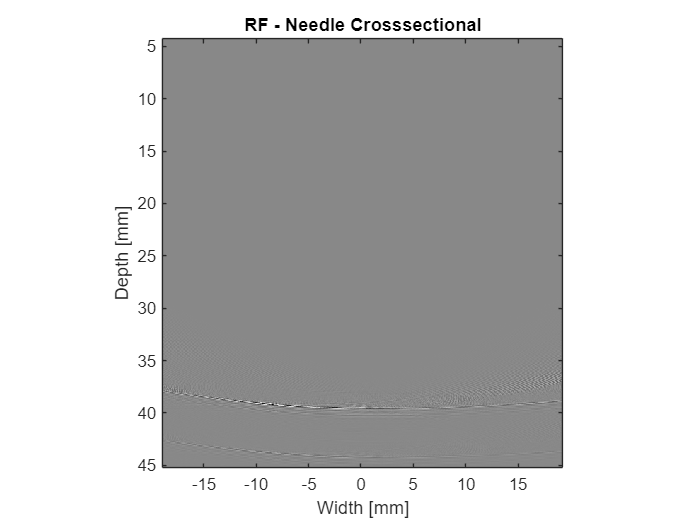

figure; imagesc(x*1e3, z(50:655)*1e3, final(50:655, :)); colormap gray; 
axis image; xlabel('Width [mm]'); ylabel('Depth [mm]'); title('RF - Needle Crosssectional');

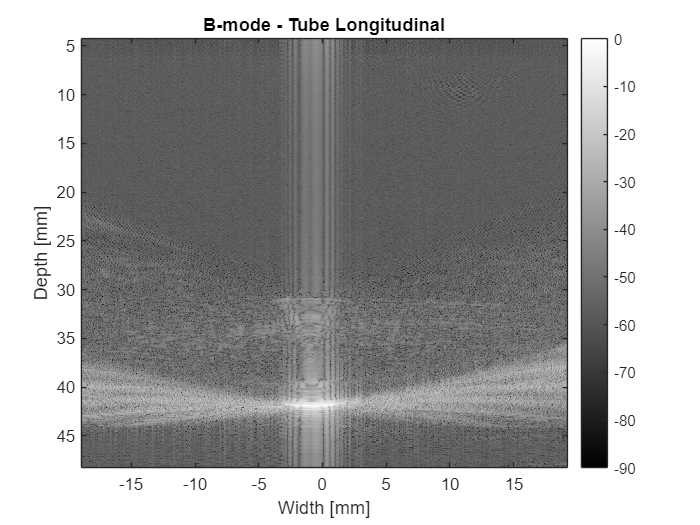

E_log = db(abs(hilbert(final(50:700, :))));
E_log = E_log - max(E_log(:));
figure; imagesc(x*1e3, z(50:700)*1e3,E_log); colormap gray; colorbar;
xlabel("Width [mm]");ylabel("Depth [mm]")
set (gca,'clim',[-90 0]);title('B-mode - Tube Longitudinal')

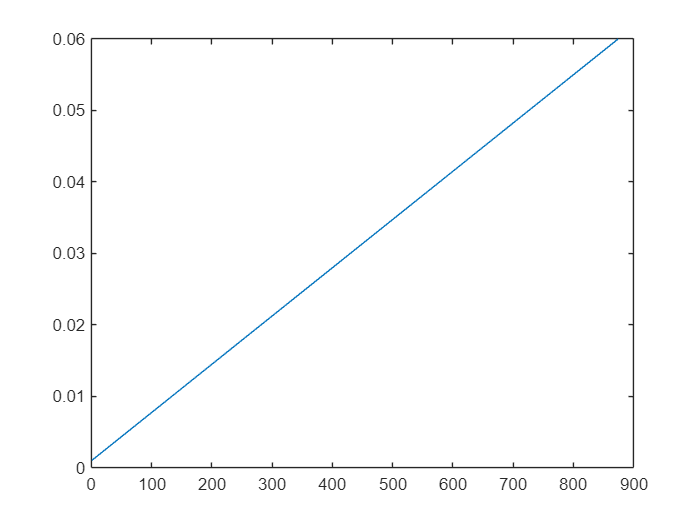

figure; plot(S);

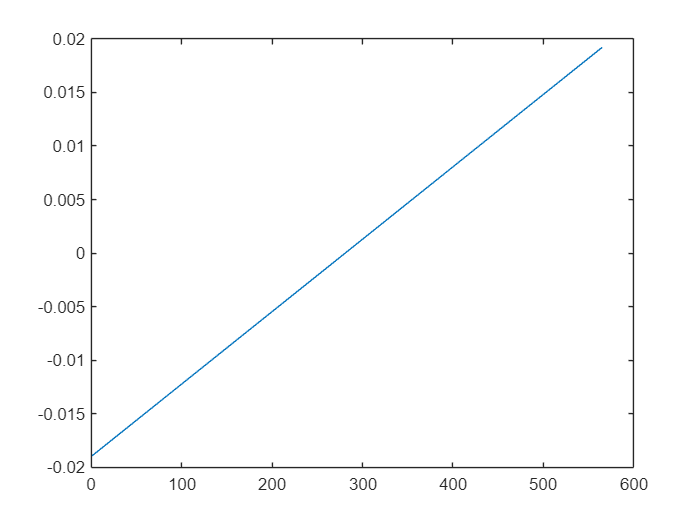

figure; plot(x);